# 判断一个POSCAR的对称性

主要包含了一些结构读取，转换，生成，以及与spglib的接口，探索一下空间操作的形式

- parkman

- [parkman@buaa.edu.cn](parkman@buaa.edu.cn)

## POSCAR的处理

### 读取POSCAR

#### **POSCAR_readin**

**example:**

- [Rm,sites,Atom_name,Atom_num]= POSCAR_readin(filename,mode)

- [Rm,sites,Atom_name,Atom_num] = POSCAR_readin(filename)

- [Rm,sites,Atom_name,Atom_num] = POSCAR_readin()

**Input:**

- POSCAR in current dir

**Output:**

- a_crystal_constance

- Rm

- Atom_name

- Atom_num

- element_information: sites unit A? e-6

**Note:**

`site=struct('seq',[],'inseq',[],'rc1',[],'rc2',[],'rc3',[],'name',[],'nameseq',[]);`

[Rm,sites,Atom_name,Atom_num] = POSCAR_readin();
%[Rm,sites,Atom_name,Atom_num] = POSCAR_readin('POSCAR');
%[Rm,sites,Atom_name,Atom_num] = POSCAR_readin('POSCAR','vasp');
Rm

Rm =     3.6136         0         0
   -1.2045    3.4069         0
   -1.2045   -1.7035    2.9505


Atom_name

Atom_name = "Na"

Atom_num

Atom_num = 1

sites

sites = 包含以下字段的 struct :
        seq: 1
      inseq: 1
        rc1: 0
        rc2: 0
        rc3: 0
       name: "Na1"
    nameseq: 1
    ion_num: 1


#### POSCAR_read

POSCAR_read;

### 展示POSCAR信息

#### POSCAR_play

POSCAR_play(sites);

1  Na1 0.000000 0.000000 0.000000 


### 简单画出元胞POSCAR

#### POSCAR_plot

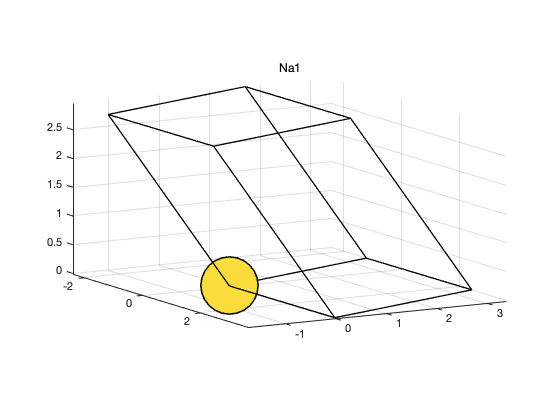

POSCAR_plot(Rm,sites,Atom_name,Atom_num);

#### POSCAR_gen

POSCAR_gen(Rm,sites,Atom_name,Atom_num);
%POSCAR_gen(Rm,sites,Atom_name,Atom_num,filename)

### 超胞

#### supercell

  Ns =

  [ N_11, N_12, N_13]

  [ N_21, N_22, N_23]

  [ N_31, N_32, N_33]

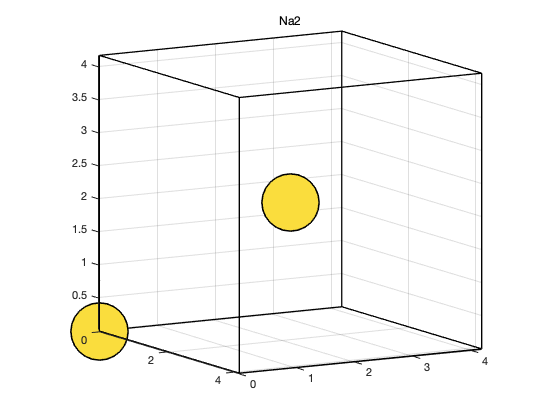

Ns = diag([2 2 1]);
[Rm,sites,Atom_name,Atom_num] = POSCAR_readin('POSCAR_conventional');
POSCAR_plot(Rm,sites,Atom_name,Atom_num);

supercell(Ns,Rm,sites,Atom_name,Atom_num);
disp(Ns);

     2     0     0
     0     2     0
     0     0     1



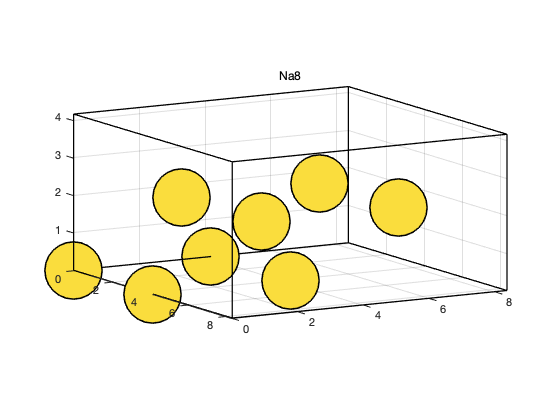

[Rm,sites,Atom_name,Atom_num] = POSCAR_readin('POSCAR_super');
POSCAR_plot(Rm,sites,Atom_name,Atom_num);

## 与spglib接口

### spglib简介

- [https://spglib.github.io/spglib/](https://spglib.github.io/spglib/)

- [https://pypi.org/project/spglib/](https://pypi.org/project/spglib/)

- [https://github.com/spglib/spglib](https://github.com/spglib/spglib)

### MATLAB调用C库

[https://ww2.mathworks.cn/help/matlab/call-c-library-functions.html](https://ww2.mathworks.cn/help/matlab/call-c-library-functions.html)

#### 调用与卸载

addpath('/usr/local/lib/');
addpath('/usr/local/include/');
warning off;

%
if not(libisloaded('libsymspg'))
    [notfound,warnings] = loadlibrary('libsymspg','spglib.h');
end
libfunctions('libsymspg');


类 lib.libsymspg 的方法:

spg_delaunay_reduce                        spg_get_error_message                      spg_get_stabilized_reciprocal_mesh         spgat_get_dataset                          
spg_find_primitive                         spg_get_grid_point_from_address            spg_get_symmetry                           spgat_get_dataset_with_hall_number         
spg_free_dataset                           spg_get_hall_number_from_symmetry          spg_get_symmetry_from_database             spgat_get_international                    
spg_get_dataset                            spg_get_international                      spg_get_symmetry_with_collinear_spin       spgat_get_multiplicity                     
spg_get_dataset_with_hall_number           spg_get_ir_reciprocal_mesh                 spg_get_symmetry_with_site_tensors         spgat_get_schoenflies                      
spg_get_dense_BZ_grid_points_by_rotations  spg_get_major_version                      spg_niggli_reduce         

libfunctionsview('libsymspg');

% unloadlibrary libsymspg

#### 调用库中的函数

[x1,...,xN] = calllib(libname,funcname,arg1,...,argN) 调用 C 库 libname 中的函数 funcname，从而传递输入参数 arg1,...,argN。calllib 函数返回从 x1,...,xN 中的 funcname 获得的输出值。

A = calllib('libsymspg','spg_get_major_version');
B = calllib('libsymspg','spg_get_minor_version');
C = calllib('libsymspg','spg_get_micro_version');
fprintf('spglib.%d.%d.%d was used',A,B,C);

spglib.1.16.1 was used

unloadlibrary libsymspg;

### spglib C-API

Always remember transpoze

addpath('/usr/local/lib/');
addpath('/usr/local/include/');
warning off;
if not(libisloaded('libsymspg'))
    [notfound,warnings] = loadlibrary('libsymspg','spglib.h');
end

#### [`spg_get_major_version`, `spg_get_minor_version`, `spg_get_micro_version`](https://spglib.github.io/spglib/api.html#id1)

New in version 1.8.3

Version number of spglib is obtained. These three functions return integers that correspond to spglib version [major].[minor].[micro].

#### [`spg_get_error_code` and `spg_get_error_message`](https://spglib.github.io/spglib/api.html#id2)[¶](https://spglib.github.io/spglib/api.html#spg-get-error-code-and-spg-get-error-message)

New in version 1.9.5

**Be careful. These are not thread safe, i.e., only safely usable when calling one spglib function per process.**

#### [`spg_get_symmetry`](https://spglib.github.io/spglib/api.html#id3)

This function finds a set of representative symmetry operations for primitive cells or its extension with lattice translations for supercells. 0 is returned if it failed.

POSCAR_read;
types = [1,1];
max_size = 96;
rotation =  libpointer('int32Ptr',zeros(3,3,max_size ));
translation = libpointer('doublePtr',zeros(3,max_size ));


lattice = Rm;
position = [[sites.rc1].',[sites.rc2].',[sites.rc3].'].';

num_atom = 1;
symprec = 0.01;
[Nsym,rotation,translation,lattice,position,types] = calllib('libsymspg','spg_get_symmetry',rotation,...
                     translation,...
                     max_size,...
                     lattice,...
                     position,...
                     types,...
                     num_atom,...
                     symprec);
rotation = reshape(rotation,3,3,[]);
for i = 1:Nsym
    rotation(:,:,i) =rotation(:,:,i).';
end
translation = translation.';
fprintf('space_group_operations:\n');
for i = 1:Nsym
    fprintf('* rotation: # %d\n',i)
    fprintf('%3d %3d %3d\n%3d %3d %3d\n%3d %3d %3d\n',...
        rotation(1,1,i),rotation(1,2,i),rotation(1,3,i),...
        rotation(2,1,i),rotation(2,2,i),rotation(2,3,i),...
        rotation(3,1,i),rotation(3,2,i),rotation(3,3,i)...
        );
    fprintf('  ---------\n');
    fprintf('  %7.5f %7.5f %7.5f\n',translation(i,1),translation(i,2),translation(i,3));
end

#### [`spg_get_international`](https://spglib.github.io/spglib/api.html#id4)

Space group type is found and returned in international table symbol to `symbol` and also as a number (return value). 0 is returned if it failed.

SG_international = libpointer('int8Ptr',zeros(11,1));
[SG_number,SG_international,~,~,~]=calllib('libsymspg','spg_get_international',SG_international,...
                     lattice,...
                     position,...
                     types,...
                     num_atom,...
                     symprec);
SG_international = strcat(char(SG_international).');
fprintf('space_group_type: %s\n',SG_international);
fprintf('space_group_number: %d\n',SG_number);

#### [`spg_get_schoenflies`](https://spglib.github.io/spglib/api.html#id5)

`sometimes`

Space group type is found and returned in schoenflies to `symbol` and also as a number (return value). 0 is returned if it failed.

SG_schoenflies = libpointer('int8Ptr',zeros(7,1));
[SG_number,SG_schoenflies,~,~,~]=calllib('libsymspg','spg_get_schoenflies',SG_schoenflies,...
                     lattice,...
                     position,...
                     types,...
                     num_atom,...
                     symprec);
SG_schoenflies= strcat(char(SG_schoenflies).');
fprintf('space_group_type(Schoenflies): %s\n',SG_schoenflies);
fprintf('space_group_number: %d\n',SG_number);

#### [`spg_standardize_cell`](https://spglib.github.io/spglib/api.html#id6)

The standardized unit cell (see [Spglib conventions of standardized unit cell](https://spglib.github.io/spglib/definition.html#def-standardized-unit-cell)) is generated from an input unit cell structure and its symmetry found by the symmetry search. The choice of the setting for each space group type is as explained for [spg_get_dataset](https://spglib.github.io/spglib/api.html#api-spg-get-dataset). Usually `to_primitive=0` and `no_idealize=0` are recommended to set and this setting results in the same behavior as `spg_refine_cell`. 0 is returned if it failed.

Number of atoms in the found standardized unit (primitive) cell is returned.

`to_primitive=1` is used to create the standardized primitive cell with the transformation matricies shown at [Transformation to the primitive cell](https://spglib.github.io/spglib/definition.html#def-standardized-primitive-cell), otherwise `to_primitive=0` must be specified. The found basis vectors and atomic point coordinates and types are overwritten in `lattice`, `position`, and `types`, respectively. Therefore with `to_primitive=0`, at a maximum four times larger array size for `position` and `types` than the those size of the input unit cell is required to store a standardized unit cell with face centring found in the case that the input unit cell is a primitive cell.

`no_idealize=0` is used to idealize the lengths and angles of basis vectors with adjusting the positions of atoms to nearest exact positions according to crystal symmetry. However the crystal can be rotated in Cartesian coordinates by the idealization of the basis vectors. `no_idealize=1` disables this. The detail of the idealization (`no_idealize=0`) is written at [Idealization of unit cell structure](https://spglib.github.io/spglib/definition.html#def-idealize-cell). `no_idealize=1` may be useful when we want to leave basis vectors and atomic positions in Cartesianl coordinates fixed.

[Rm,sites,Atom_name,Atom_num] = POSCAR_readin('POSCAR_super');
lattice = Rm;
num_atom = sum(Atom_num);
position = [[sites.rc1].',[sites.rc2].',[sites.rc3].'].';
to_primitive = 1 ;
no_idealize  = 0 ;
types = [];
for i = 1:length(Atom_num)
    types = [types;ones(1,Atom_num(i)*i)];
end
[num_atom,lattice_new,position_new,types_new]=calllib('libsymspg','spg_standardize_cell',...
                     lattice,...
                     position,...
                     types,...
                     num_atom,...
                     to_primitive,...
                     no_idealize,...
                     symprec);

#### [`spg_get_dataset` and `spg_get_dataset_with_hall_number`](https://spglib.github.io/spglib/api.html#id9)

This function allows to directly access to the space-group-type database in spglib (spg_database.c). To specify the space group type with a specific choice, `hall_number` is used. The definition of `hall_number` is found at [Space group type](https://spglib.github.io/spglib/dataset.html#dataset-spg-get-dataset-spacegroup-type). `number` `=` `0` is returned when it failed.

% hall_number = 166;
[Rm,sites,Atom_name,Atom_num] = POSCAR_readin('POSCAR');
lattice = Rm;
types = [];
for i = 1:length(Atom_num)
    types = [types;ones(1,Atom_num(i)*i)];
end
num_atom = sum(Atom_num);
symprec = 0.01;
position = [[sites.rc1].',[sites.rc2].',[sites.rc3].'].';
% SpglibDatasetPtr = calllib('libsymspg','spg_free_dataset',SpglibDatasetPtr );


SpglibDatasetPtr = libpointer('SpglibDatasetPtr');

[SpglibDatasetPtr,~,~,~] = calllib('libsymspg','spg_get_dataset',lattice,position,types,num_atom,symprec);

% SpglibDataset = calllib('libsymspg','spg_free_dataset',SpglibDatasetPtr);
%strcat(char(SpglibDataset.international_symbol));
%strcat(char(SpglibDataset.hall_symbol));
%clear SpglibDatasetPtr;
% calllib('libsymspg','spg_get_dataset_with_hall_number',hall_number)

#### [`spg_get_symmetry_from_database`](https://spglib.github.io/spglib/api.html#id12)

This function allows to directly access to the space group operations in the spglib database (spg_database.c). To specify the space group type with a specific choice, `hall_number` is used. The definition of `hall_number` is found at [Space group type](https://spglib.github.io/spglib/dataset.html#dataset-spg-get-dataset-spacegroup-type). 0 is returned when it failed.

 hall_number = SpglibDataset.hall_number;
 max_size = 192;
 rotation =  libpointer('int32Ptr',zeros(3,3,max_size ));
 translation = libpointer('doublePtr',zeros(3,max_size ));
%[hall_number, rotation ,  translation]  =
 [Nsym, rotation ,  translation]  = calllib('libsymspg','spg_get_symmetry_from_database',rotation, translation,hall_number);
                  rotation = reshape(rotation,3,3,[]);
                 for i = 1:Nsym
                     rotation(:,:,i) =rotation(:,:,i).';
                 end
                 rotation(:,:,Nsym+1:end) = [] ;
                 translation = translation.';
                 translation(Nsym+1:end,:) = [] ;